clear; clc; close all;

restoredefaultpath;
addpath("../spm/"); % Add path for SPM
spm('defaults','FMRI');
spm_jobman('initcfg');

## DCM for fMRI - 2nd level (Language)

dirGLM = '/Users/abhijitc/Documents/Abhijit/LenaLab_DCM/SPM4_Language2/second_level/';

load(fullfile(dirGLM, "design_matrix.mat"));

## PEB specification



------------------------------------------------------------------------
15-Jul-2025 19:10:03 - Running job #1
------------------------------------------------------------------------
15-Jul-2025 19:10:03 - Running 'Specify / Estimate PEB'
VL Iteration 1       : F = -269508.72 dF: 0.0000  [-3.75]
VL Iteration 2       : F = -268591.99 dF: 916.7308  [-3.50]
VL Iteration 3       : F = -268174.76 dF: 417.2233  [-3.25]
VL Iteration 4       : F = -267782.90 dF: 391.8663  [-3.00]
VL Iteration 5       : F = -267432.65 dF: 350.2514  [-2.75]
VL Iteration 6       : F = -267144.57 dF: 288.0729  [-2.50]
VL Iteration 7       : F = -266919.89 dF: 224.6827  [-2.25]
VL Iteration 8       : F = -266750.03 dF: 169.8603  [-2.00]
VL Iteration 9       : F = -266624.06 dF: 125.9709  [-1.75]
VL Iteration 10      : F = -266519.58 dF: 104.4789  [-1.50]
VL Iteration 11      : F = -266418.52 dF: 101.0619  [-1.25]
VL Iteration 12      : F = -266315.76 dF: 102.7594  [-1.00]
VL Iteration 13      : F = -266209.92 dF

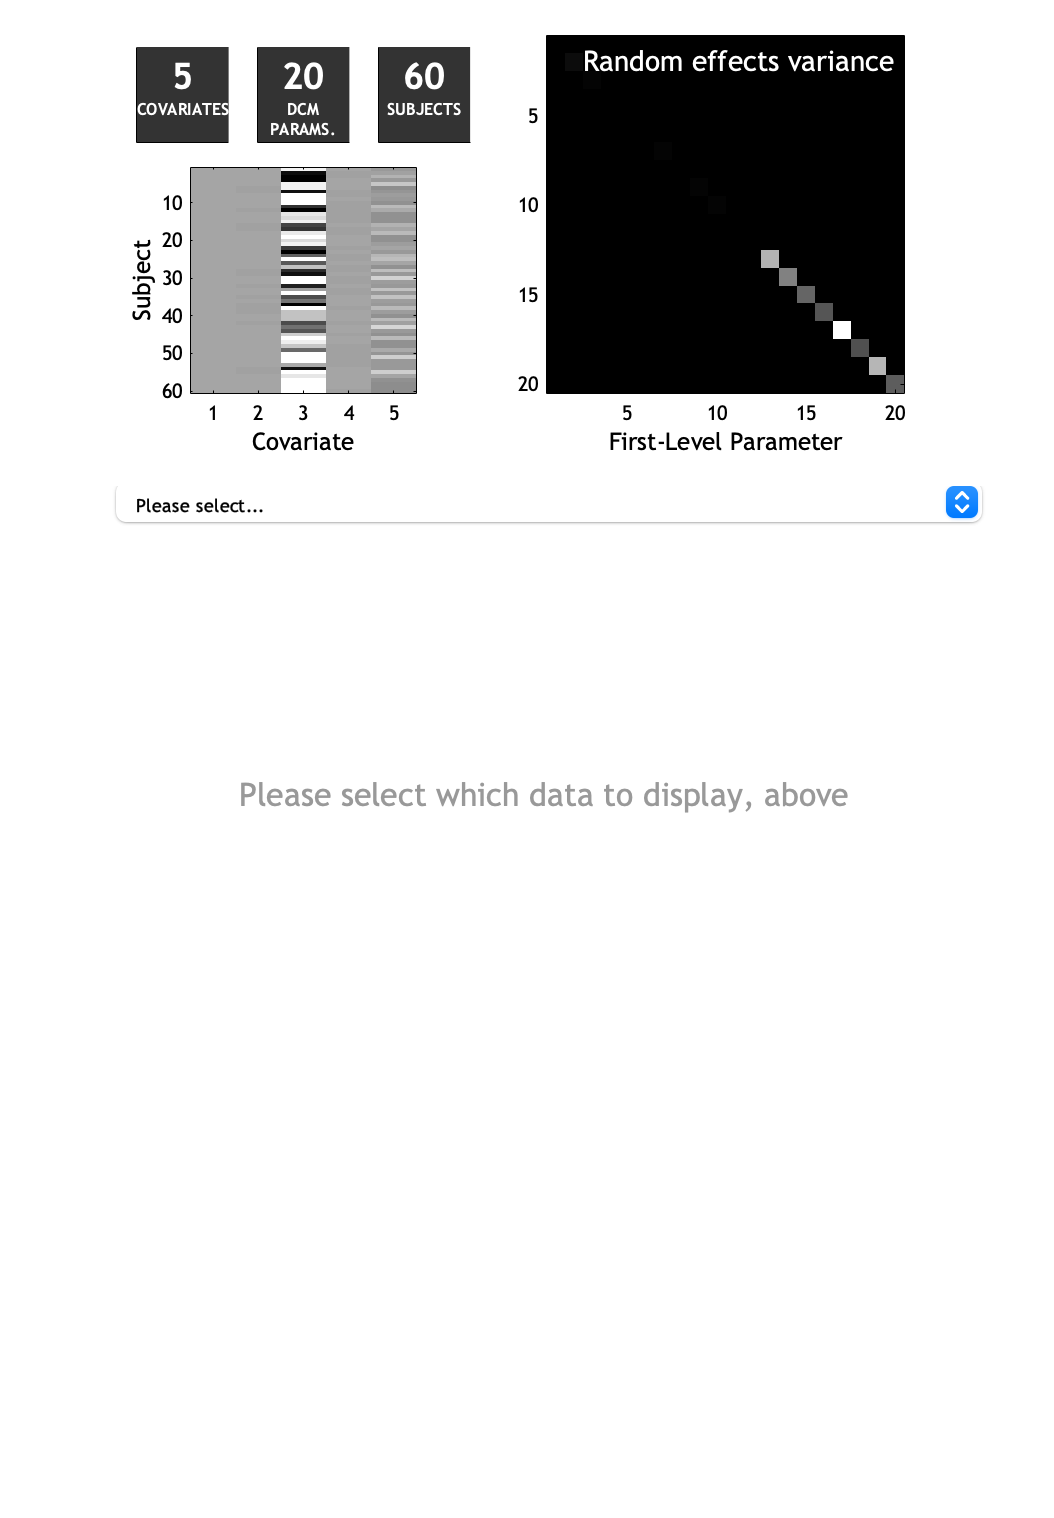

15-Jul-2025 19:11:23 - Done    'Specify / Estimate PEB'
15-Jul-2025 19:11:23 - Done



clear matlabbatch;
matlabbatch{1}.spm.dcm.peb.specify.name = 'm1';
matlabbatch{1}.spm.dcm.peb.specify.model_space_mat = {fullfile(dirGLM,'GCM_m1_pre_estimated.mat')};
matlabbatch{1}.spm.dcm.peb.specify.dcm.index = 1;
matlabbatch{1}.spm.dcm.peb.specify.cov.design_mtx.cov_design = X;
matlabbatch{1}.spm.dcm.peb.specify.cov.design_mtx.name = labels;
matlabbatch{1}.spm.dcm.peb.specify.fields.default = {'B'}';
% matlabbatch{1}.spm.dcm.peb.specify.priors_between.components = 'All';
% matlabbatch{1}.spm.dcm.peb.specify.priors_between.ratio = 16;
% matlabbatch{1}.spm.dcm.peb.specify.priors_between.expectation = 0;
% matlabbatch{1}.spm.dcm.peb.specify.priors_between.var = 0.0625;
% matlabbatch{1}.spm.dcm.peb.specify.priors_glm.group_ratio = 1;
% matlabbatch{1}.spm.dcm.peb.specify.estimation.maxit = 64;
matlabbatch{1}.spm.dcm.peb.specify.show_review = 1;
spm_jobman('run',matlabbatch); 

## Bayesian model comparison



------------------------------------------------------------------------
15-Jul-2025 19:12:20 - Running job #1
------------------------------------------------------------------------
15-Jul-2025 19:12:20 - Running 'Compare / Average PEB models'
BMC: 100% 
7 models in Occams window:
	Model 1, p(m|Y)=0.00
	Model 2, p(m|Y)=0.01
	Model 3, p(m|Y)=0.00
	Model 4, p(m|Y)=0.44
	Model 5, p(m|Y)=0.09
	Model 6, p(m|Y)=0.38
	Model 7, p(m|Y)=0.08
Averaging models in Occams window...


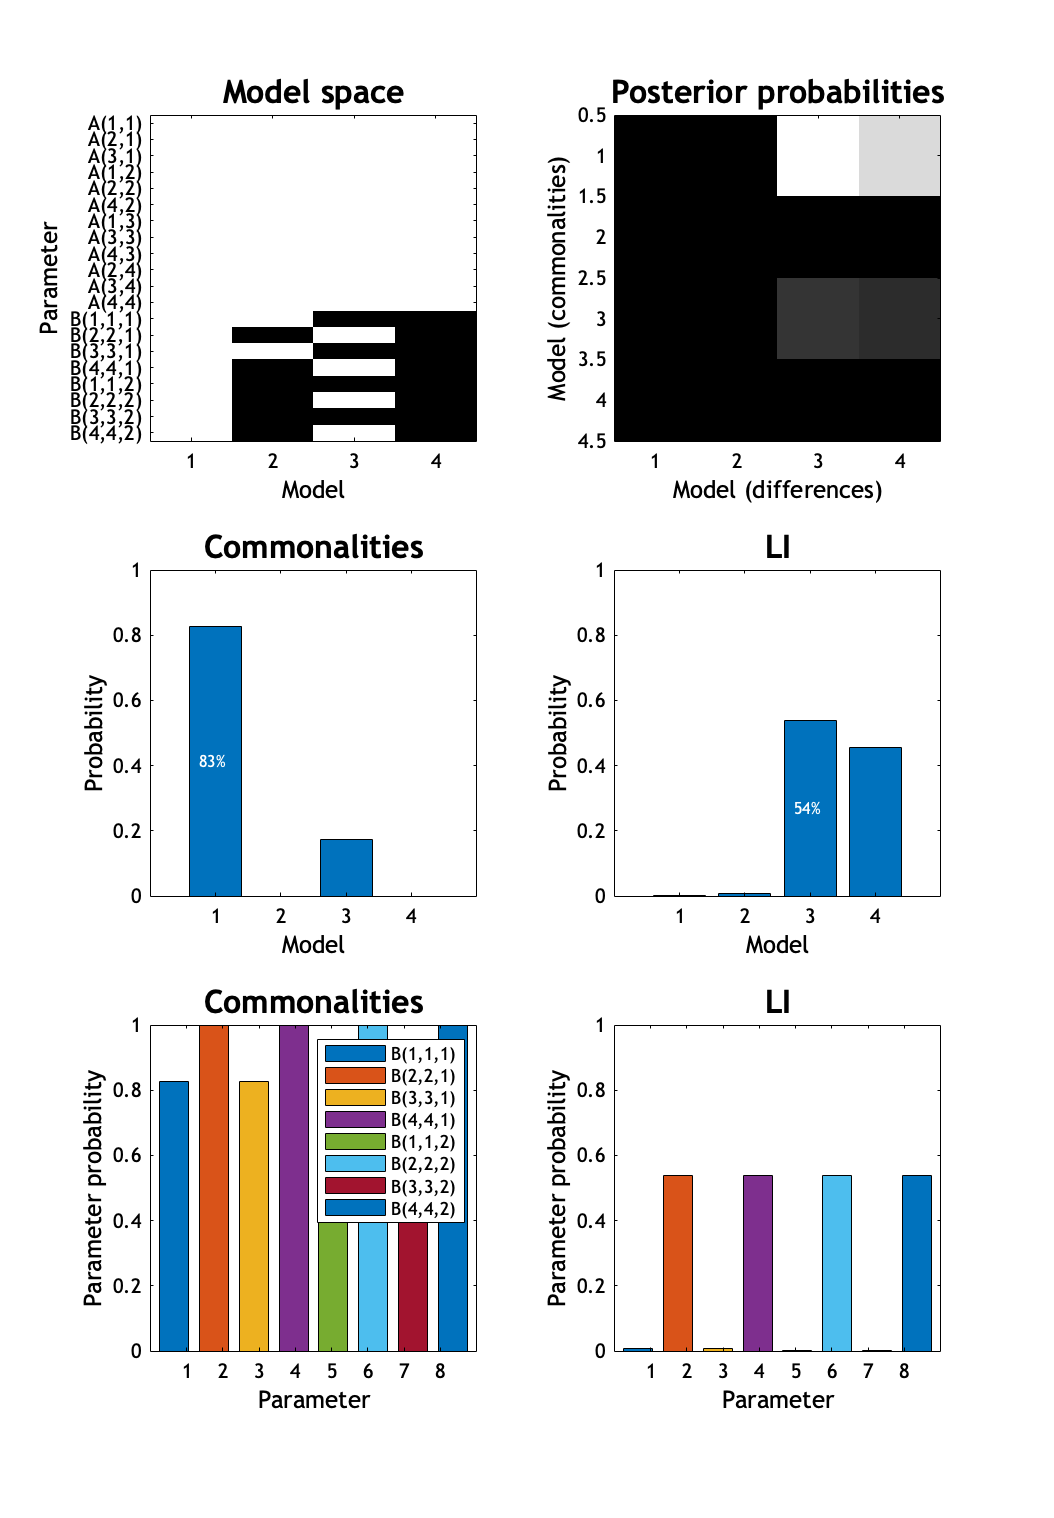

15-Jul-2025 19:12:26 - Done    'Compare / Average PEB models'
15-Jul-2025 19:12:26 - Done



clear matlabbatch;
matlabbatch{1}.spm.dcm.peb.compare.peb_mat = {fullfile(dirGLM,'PEB_m1.mat')};
matlabbatch{1}.spm.dcm.peb.compare.model_space_mat = {fullfile(dirGLM,'GCM_templates.mat')}; 
matlabbatch{1}.spm.dcm.peb.compare.show_review = 1;
spm_jobman('run',matlabbatch); 